## Confidence intervals

For this week we will be using the real data you are working on, but more as a background for the main activity rather than in depth explorations. Don't worry, more in-depth exploration the next two weeks!**Setup**

First, we want to have some `background' data (presumably signal free) onto which we can inject a simulated signal. So the first step is to isolate some appropriate data from your data files. 

HERA

For the HERA data, it is suggested that you take the absolute value of the complex visibilities to make a one dimensional (positive definite) background dataset. You don't need to read in the entire file, a million points should be sufficient. 

LHC

For the LHC data, we are going to have to fake a background. Make a Poisson background with mean 100. 

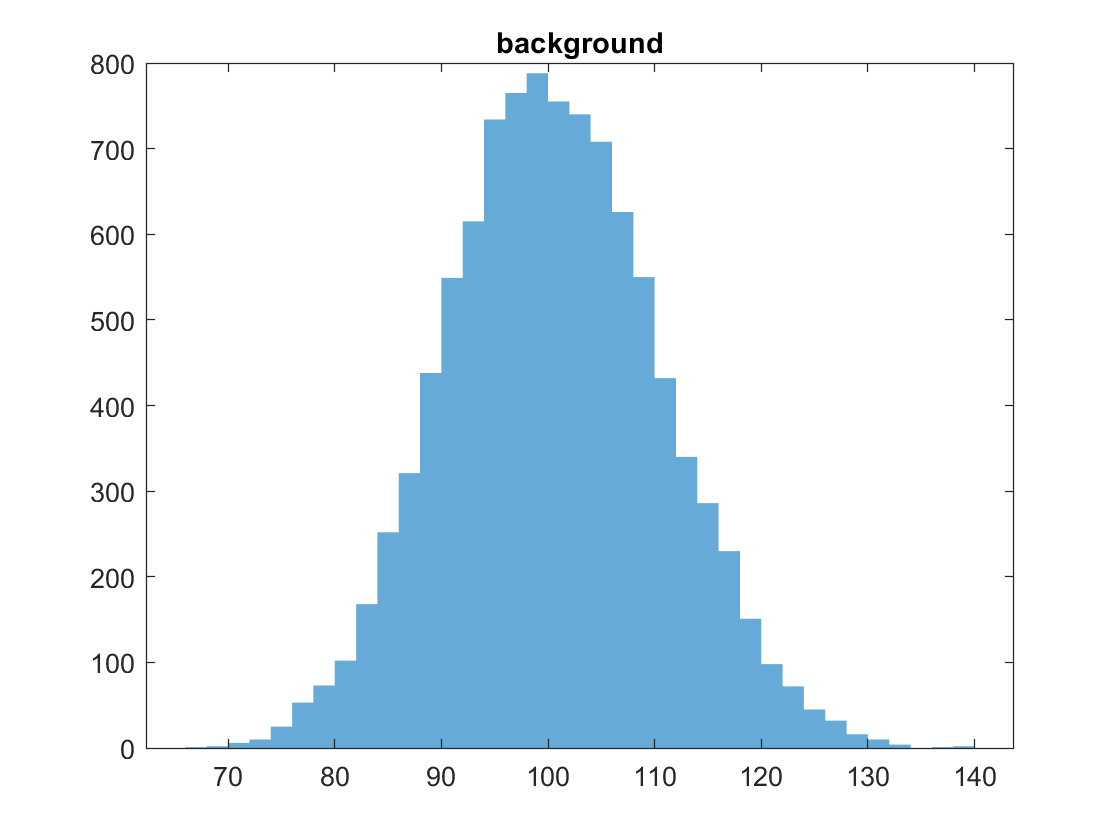

clc; clear; close all;
PoissonMean100 = makedist('Poisson',"lambda",100);
BackgroundData = random(PoissonMean100,[1 10000]);
figure;
histogram(BackgroundData,"EdgeColor","none");
title('background');

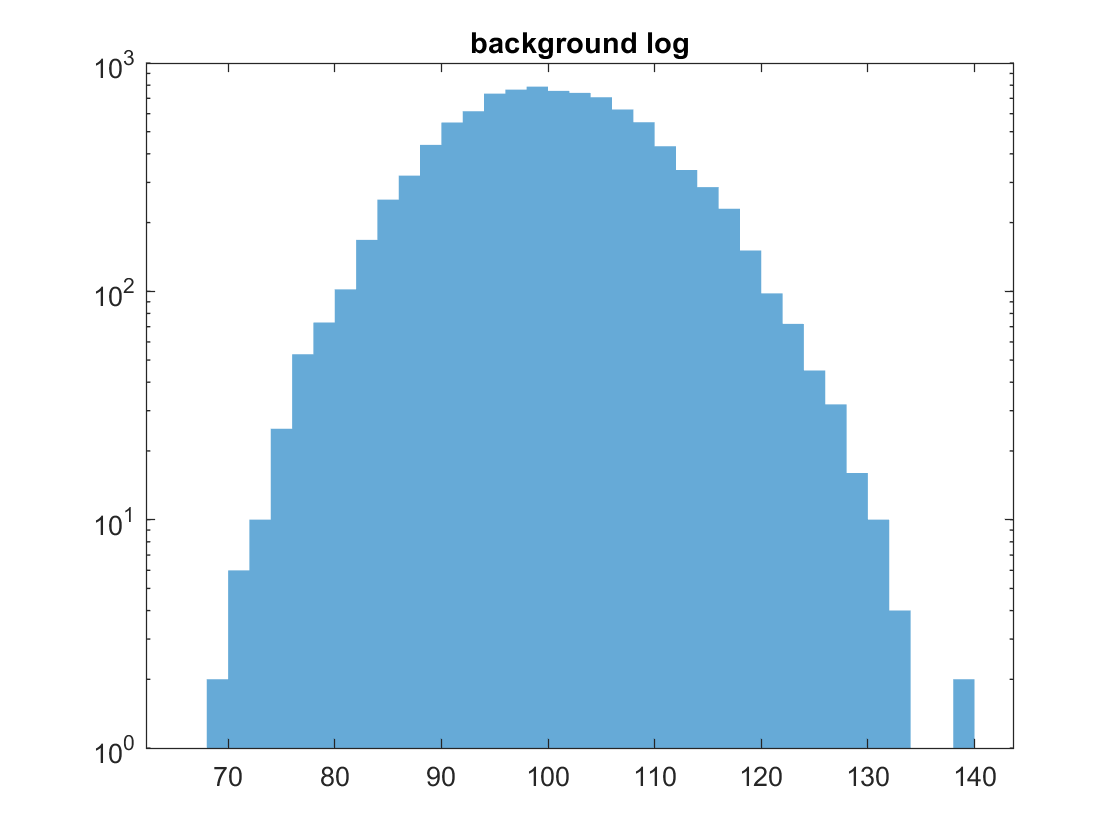

figure;
histogram(BackgroundData,"EdgeColor","none");
set(gca,'YScale',"log");
title('background log');

**Problem 1**

The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]

Prob5Sigma = 2.8571e-7

Prob5Sigma = 2.8571e-07


Thresh5Sigma = icdf(PoissonMean100,1-Prob5Sigma)

Thresh5Sigma = 154

**Problem 2**

Now create a set of injected (simulated) signals of a *single strength*. You will want to make your signal moderately strong, say somewhere in the 8-30σ range. Inject this signal into your background data many times.

a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.

b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?

Prob8Sigma = 6.22096e-16

Prob8Sigma = 6.2210e-16

Thresh8Sigma = icdf(PoissonMean100,1-Prob8Sigma)

Thresh8Sigma = 190

size = 10000;
signal = zeros(1,size);
signal(randi(numel(signal),[1,500])) = 90

signal =      0     0     0     0     0     0     0     0     0     0     0     0     0    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    90     0     0    90     0     0     0     0     0    90     0     0     0     0     0     0     0     0     0


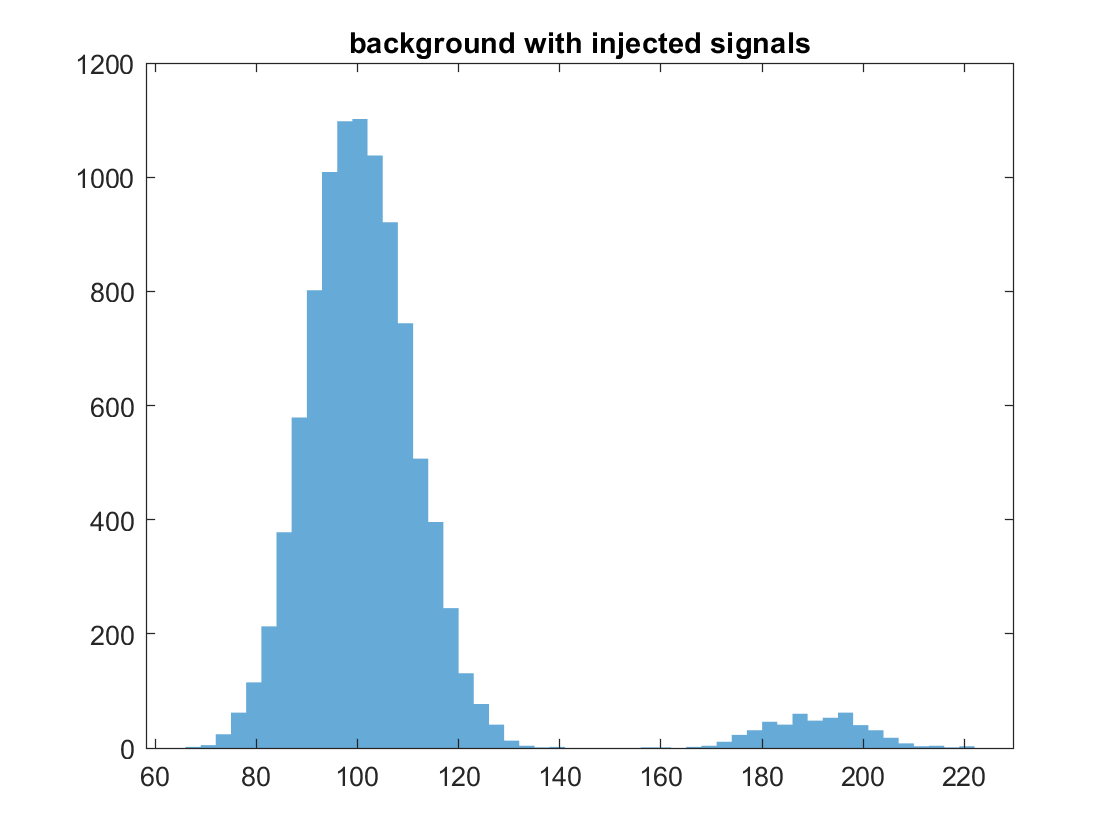

obssiganl = BackgroundData + signal;
figure;
histogram(obssiganl,"EdgeColor","none")
title('background with injected signals');

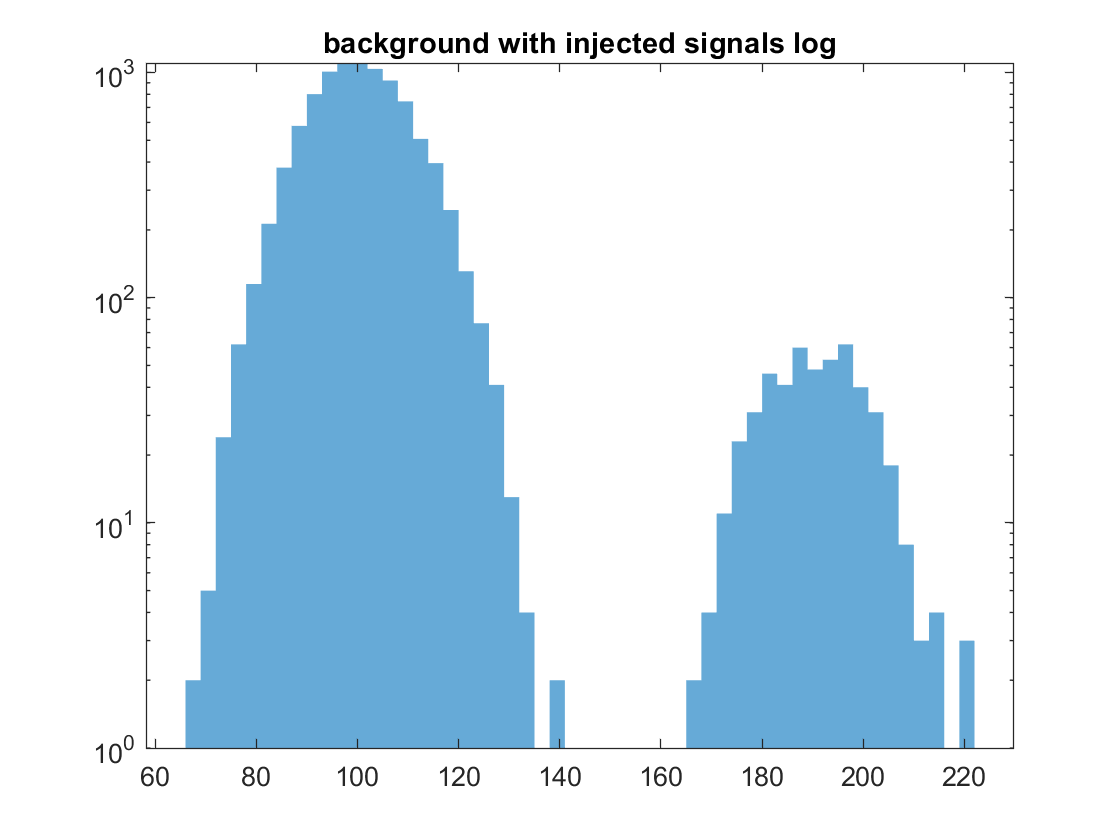

figure;
histogram(obssiganl,"EdgeColor","none");
set(gca,'YScale',"log");
title('background with injected signals log');

**Problem 3**

Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). 

a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal


signalstrength = linspace(0,300,10000);
[scratch, signal2] = meshgrid(signalstrength);
obssignal2 = BackgroundData + signal2

obssignal2 =   107.0000   93.0000  107.0000   93.0000   97.0000  102.0000   86.0000   95.0000  103.0000  104.0000   85.0000  117.0000  100.0000   89.0000  112.0000  115.0000   91.0000  102.0000   93.0000  107.0000  102.0000   93.0000  128.0000   90.0000   89.0000  108.0000   96.0000  115.0000   99.0000   93.0000  103.0000  102.0000  109.0000   88.0000   79.0000   88.0000   97.0000   96.0000  109.0000  114.0000  100.0000  108.0000  108.0000   98.0000   95.0000  103.0000   97.0000  110.0000  100.0000   75.0000
  107.0300   93.0300  107.0300   93.0300   97.0300  102.0300   86.0300   95.0300  103.0300  104.0300   85.0300  117.0300  100.0300   89.0300  112.0300  115.0300   91.0300  102.0300   93.0300  107.0300  102.0300   93.0300  128.0300   90.0300   89.0300  108.0300   96.0300  115.0300   99.0300   93.0300  103.0300  102.0300  109.0300   88.0300   79.0300   88.0300   97.0300   96.0300  109.0300  114.0300  100.0300  108.0300  108.0300   98.0300   95.0300  103.0300   97.0300  110.0300  100.

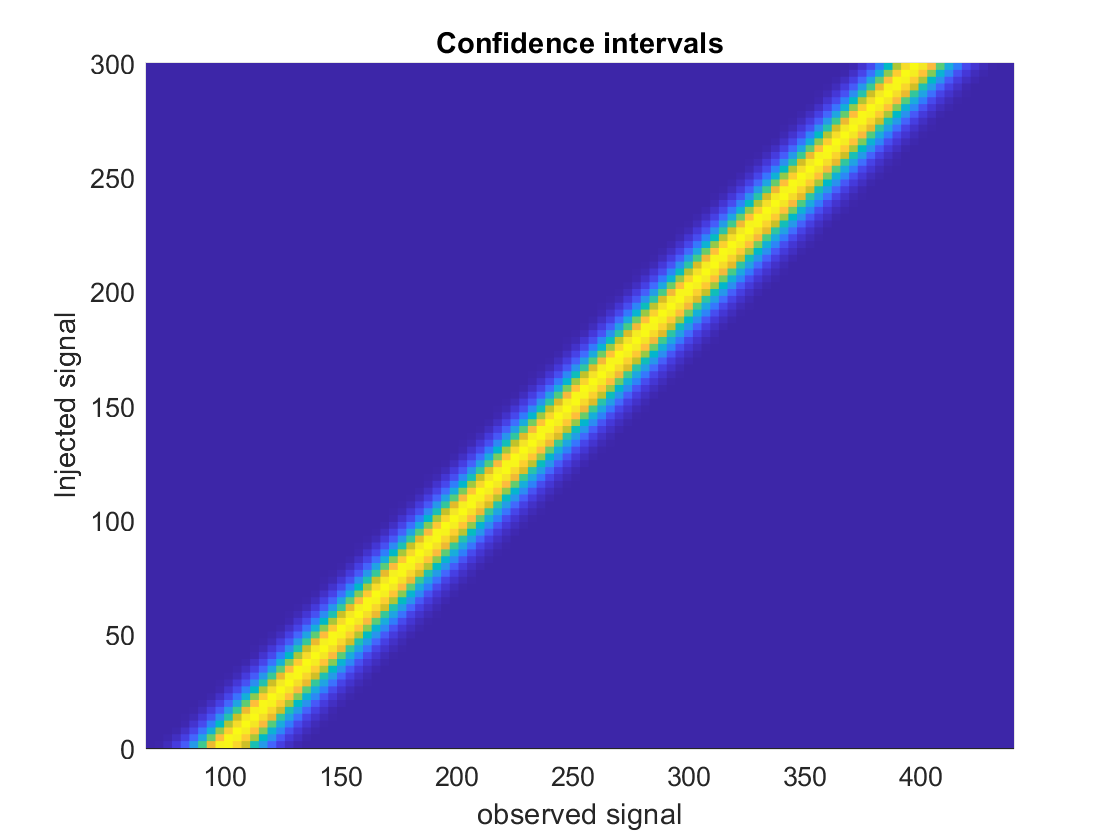

figure;
h = histogram2(obssignal2,signal2,100,'DisplayStyle','tile','ShowEmptyBins','on');
ylabel("Injected signal")
xlabel("observed signal")
title("Confidence intervals")

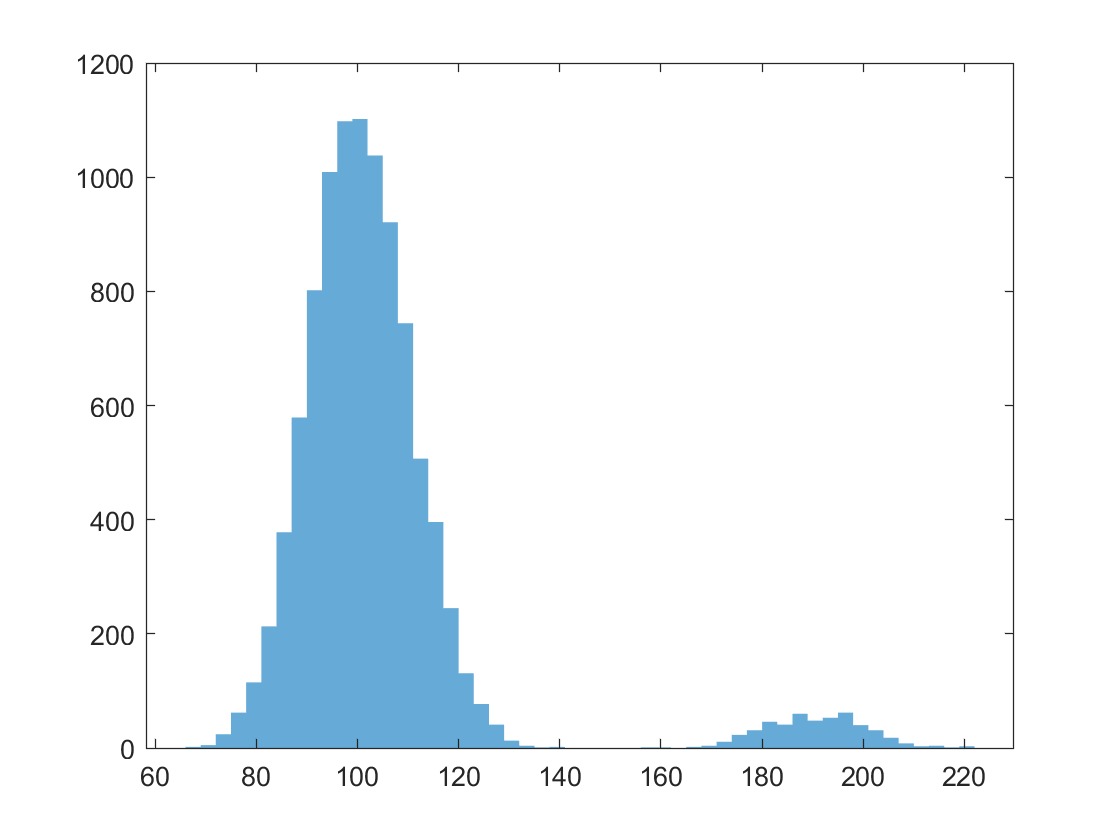

figure;
histogram(obssiganl,"EdgeColor","none")

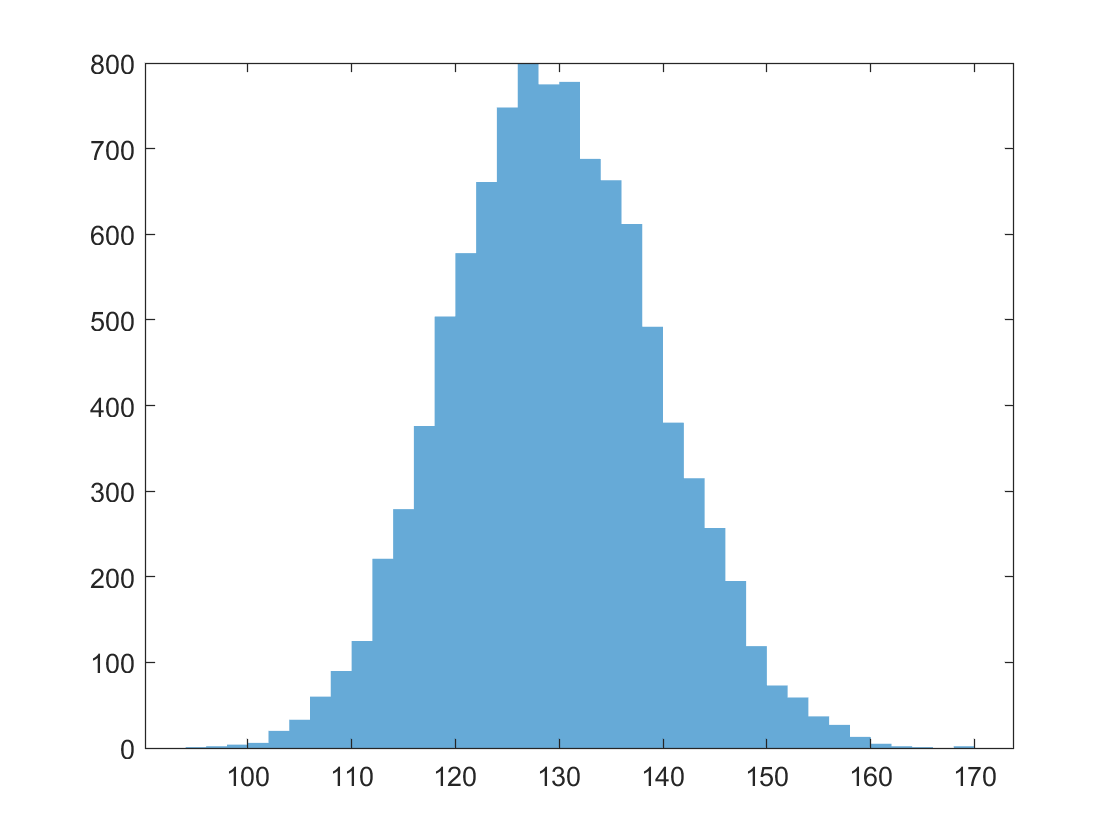

figure;
histogram(obssignal2(1000,:),"EdgeColor","none")

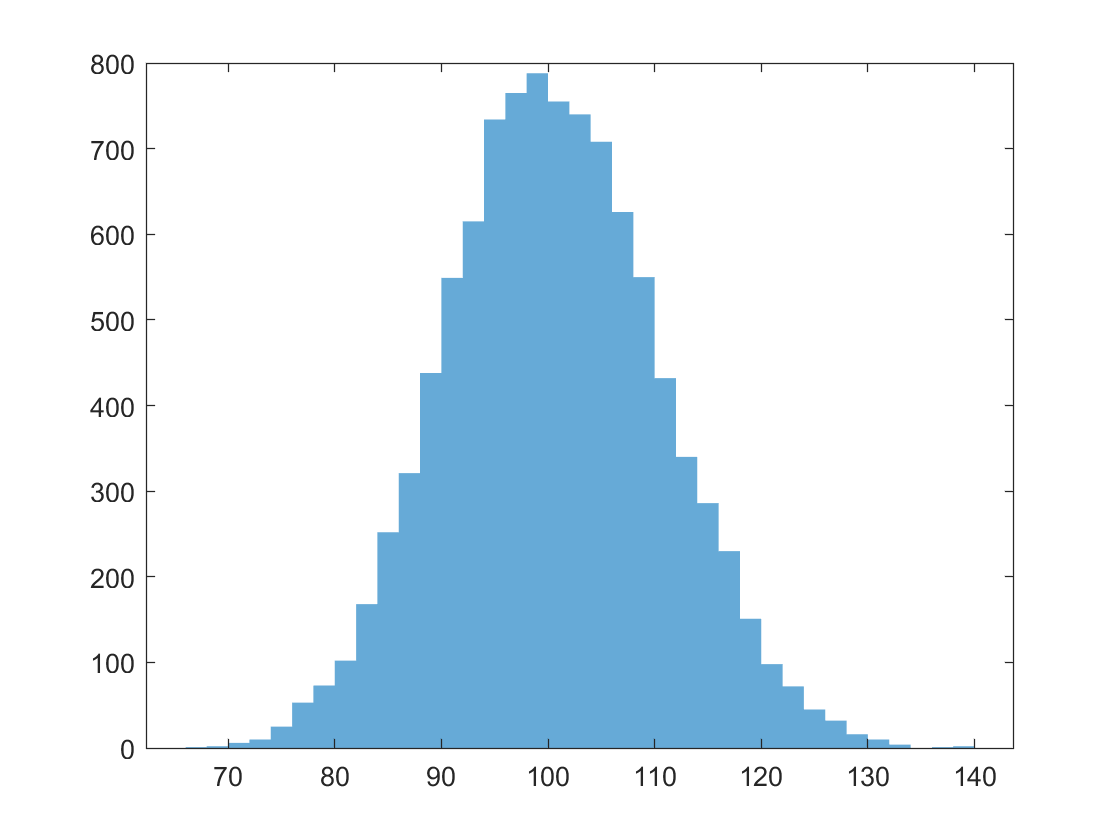

figure;
histogram(obssignal2(1,:),"EdgeColor","none")